# Runs the quality analysis of a network.

### This example contains: 

- Load a network. 

- Compute Quality without MSX. 

- Compute Quality step by step. 

- Load EPANET-MSX files. 

- Compute Quality with MSX (specify type). 

- Get quality of specific nodes. 

- Get quality of specific links. 

- Get species names. 

- Get quality for specific species type (nodes and links). 

- Plot concentration for specific node and all species. 

- Plot concentration for specific link and all species. 

- Unload libraries.

### Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Run Water Quality analysis of a network

###  Load a network.

d = epanet('net2-cl2.inp');

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded sucessfuly.


###  Compute Quality without MSX. (This function contains events)

qual_res = d.getComputedQualityTimeSeries % Value x Node, Value x Link)

qual_res = struct with fields:
            Time: [661×1 double]
     NodeQuality: [661×36 double]
     LinkQuality: [661×40 double]
    MassFlowRate: [661×36 double]


###  Compute Quality step by step.

d.solveCompleteHydraulics;
d.openQualityAnalysis;
d.initializeQualityAnalysis;
tleft=1; P=[];T=[];QsN=[]; QsL=[]; 
while (tleft>0)
    % Add code which changes something related to quality
    t = d.runQualityAnalysis;
    P = [P; d.getNodePressure];
    QsN = [QsN; d.getNodeActualQuality];
    QsL = [QsL; d.getLinkQuality];
    T = [T; t];
    tleft = d.stepQualityAnalysisTimeLeft;
end
d.closeQualityAnalysis;

###  Load EPANET-MSX files.

d.loadMSXFile('net2-cl2.msx')

###  Compute Quality with MSX (specify type).

qual_res_MSX = d.getMSXComputedQualitySpecie('CL2')

qual_res_MSX = struct with fields:
    NodeQuality: [661×36 double]
    LinkQuality: [661×40 double]
           Time: [661×1 double]


###  Get quality of specific nodes.

sensor_index = [2, 3, 5];
sensors_names = d.getNodeNameID(sensor_index)

sensors_names = 1×3 cell array
    {'2'}    {'3'}    {'5'}


QN = d.getMSXComputedQualityNode(sensor_index)

QN = struct with fields:
    Quality: {[661×1 double]  [661×1 double]  [661×1 double]}
       Time: [661×1 double]


###  Get quality of specific links.

QL = d.getMSXComputedQualityLink(sensor_index)

QL = struct with fields:
    Quality: {[661×1 double]  [661×1 double]  [661×1 double]}
       Time: [661×1 double]


###  Get species names.

type = d.getMSXSpeciesNameID;

###  Get quality for specific species type (nodes and links).

for species = type
    MSX_comp = d.getMSXComputedQualitySpecie(species{1})
end

MSX_comp = struct with fields:
    NodeQuality: [661×36 double]
    LinkQuality: [661×40 double]
           Time: [661×1 double]


###  Plot concentration for specific node and all species.

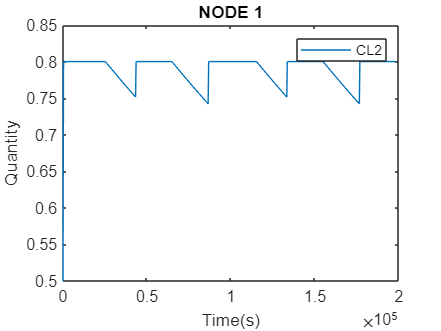

d.plotMSXSpeciesNodeConcentration(1,1:d.MSXSpeciesCount)

###  Plot concentration for specific link and all species.

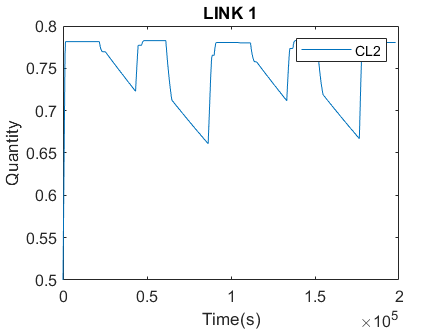

d.plotMSXSpeciesLinkConcentration(1,1:d.MSXSpeciesCount)

####  Unload libraries.

d.unloadMSX;

MSX unloaded


d.unload;

EPANET Class is unloaded
